Cases = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Confirmed_Cases_CC.csv', 'ReadVariableNames',1);

Cases = table2array(Cases(:,[13:173])); 
Cases = max(Cases,[], 2);


Deaths = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/COVID/CC_COVID/Deaths_CC.csv', 'ReadVariableNames',1);

Deaths = table2array(Deaths(:,[13:173])); 
Deaths = max(Deaths,[],2);

Confounding = readtable('/Users/Ashlynn/Desktop/Summer 2020/Honours-ECE579a/Code_Fresh/Datasets/Confounding/Confounding_Dataset.csv', 'ReadVariableNames',1);

% Data = Confounding;
% Data.Cases = Cases;
% Data.Deaths = Deaths; 
% 
% Data(:,[4:14]); 
% Data = table2array(Data(:,[4:14]));

Total_Population = (Confounding.TOT_POP);
Pop_Density = (Confounding.POP_DENSITY);
Black_Pct = (Confounding.BLACK_PCT);
Hisp_Pct = (Confounding.HISPANIC_PCT);
Over_70_Pct = (Confounding.OVER_70_PCT);
Health_Ins_Pct = (Confounding.HLTH_INS_PCT); 
Poverty_Pct = (Confounding.PCT_POVERTY);

% Cases vs total pop % 
c = corrcoef(Cases, Total_Population); 
c = c(1,2);
fprintf('Correlation coefficent between cases and total population is %f \n', c)

Correlation coefficent between cases and total population is 0.195522 



figure(1)
subplot(2,1,1)
plot(Total_Population,Cases, '*')
ylim([0,60000])
title('Cases vs Total Population')
ylabel('Cases')
xlabel('Total_Population')

% Deaths vs total pop% 
c = corrcoef(Deaths, Total_Population);
c = c(1,2);
fprintf('Correlation coefficent between deaths and total population is %f \n', c)

Correlation coefficent between deaths and total population is 1.736877e-01 


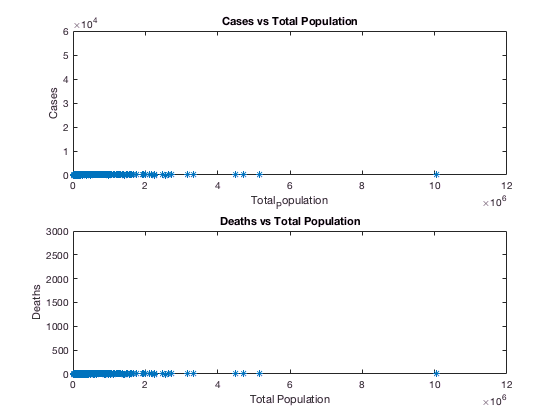


subplot(2,1,2)
plot(Total_Population,Deaths, '*')
title('Deaths vs Total Population')
ylim([0,3000])
ylabel('Deaths')
xlabel('Total Population')

Cases = Cases./Total_Population;
Deaths = Deaths./Total_Population;

c = corrcoef(Cases, Total_Population); 
c = c(1,2);
fprintf('After Normalization the correlation coefficent between cases and total population is %f \n', c)

After Normalization the correlation coefficent between cases and total population is 1.955215e-01 



c = corrcoef(Deaths, Total_Population);
c = c(1,2);
fprintf('After Normalization the correlation coefficent between deaths and total population is %f \n', c)

After Normalization the correlation coefficent between deaths and total population is 1.736877e-01 


% Cases vs pop density% 
c = corrcoef(Cases, Pop_Density); 
c = c(1,2);
fprintf('Correlation coefficent between cases and population desnsity is %f \n', c)

Correlation coefficent between cases and population desnsity is 1.386298e-01 



figure(2)
subplot(2,1,1)
plot(Pop_Density,Cases, '*')
title('Cases vs Population Density')
ylabel('Cases')
xlabel('Population Density')

% Deaths vs total pop% 
c = corrcoef(Deaths, Pop_Density);
c = c(1,2);
fprintf('Correlation coefficent between deaths and population density is %f \n', c)

Correlation coefficent between deaths and population density is 1.909126e-01 


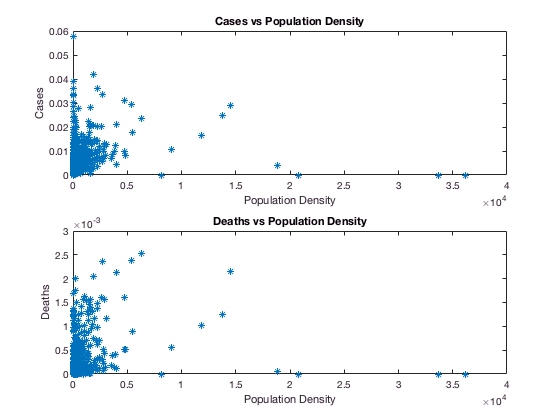


subplot(2,1,2)
plot(Pop_Density,Deaths, '*')
title('Deaths vs Population Density')
ylabel('Deaths')
xlabel('Population Density')

% Cases vs black pct % 
c = corrcoef(Cases, Black_Pct); 
c = c(1,2);
fprintf('Correlation coefficent between cases and black percent of the population is %f \n', c)

Correlation coefficent between cases and black percent of the population is 3.666963e-01 



figure(3)
subplot(2,1,1)
plot(Black_Pct,Cases, '*')
title("Cases vs Black Percent of Population")
ylabel('Cases')
xlabel('Black Percent of Population')

% Deaths vs black pct% 
c = corrcoef(Deaths, Black_Pct);
c = c(1,2);
fprintf('Correlation coefficent between deaths and black percent of the population is %f \n', c)

Correlation coefficent between deaths and black percent of the population is 3.341716e-01 


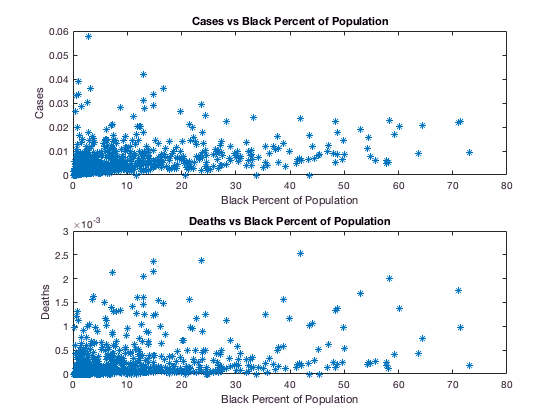


subplot(2,1,2)
plot(Black_Pct,Deaths, '*')
title("Deaths vs Black Percent of Population")
ylabel('Deaths')
xlabel('Black Percent of Population')

% Cases vs Hispanic pct % 
c = corrcoef(Cases, Hisp_Pct); 
c = c(1,2);
fprintf('Correlation coefficent between cases and hispanic percent of the population is %f \n', c)

Correlation coefficent between cases and hispanic percent of the population is 2.957398e-01 



figure(4)
subplot(2,1,1)
plot(Hisp_Pct,Cases, '*')
title("Cases vs Hispanic Percent of Population")
ylabel('Cases')
xlabel('Hispanic Percent of Population')

% Deaths vs Hispanic pct% 
c = corrcoef(Deaths, Hisp_Pct);
c = c(1,2);
fprintf('Correlation coefficent between deaths and hispanic percent of the population is %f \n', c)

Correlation coefficent between deaths and hispanic percent of the population is 6.442060e-02 


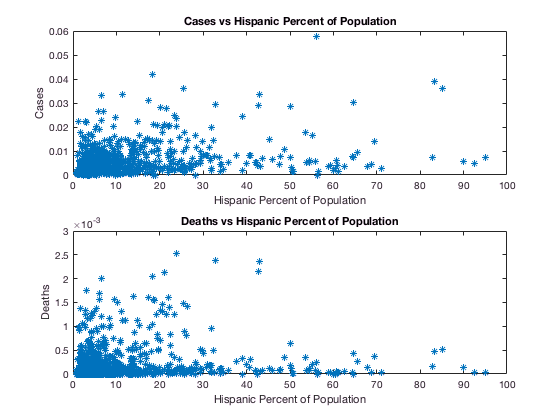


subplot(2,1,2)
plot(Hisp_Pct,Deaths, '*')
title("Deaths vs Hispanic Percent of Population")
ylabel('Deaths')
xlabel('Hispanic Percent of Population')

% Cases vs pct over 70 % 
c = corrcoef(Cases, Over_70_Pct); 
c = c(1,2);
fprintf('Correlation coefficent between cases and percent of the population over 70 is %f \n', c)

Correlation coefficent between cases and percent of the population over 70 is -2.372685e-01 



figure(5)
subplot(2,1,1)
plot(Over_70_Pct,Cases, '*')
title("Cases vs Percent of Population Over 70")
ylabel('Cases')
xlabel('Percent of Population Over 70')

% Deaths vs over 70 pct% 
c = corrcoef(Deaths, Over_70_Pct);
c = c(1,2);
fprintf('Correlation coefficent between deaths and percent of the population over 70 is %f \n', c)

Correlation coefficent between deaths and percent of the population over 70 is -1.242345e-01 


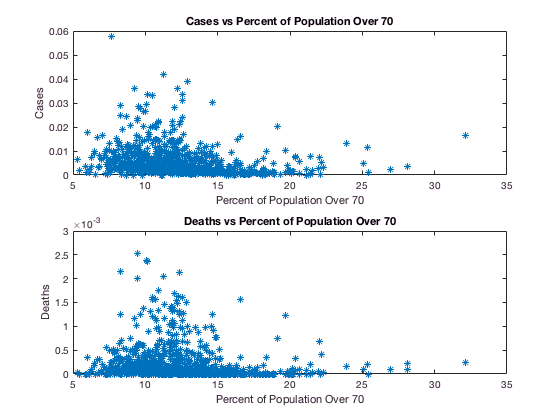


subplot(2,1,2)
plot(Over_70_Pct,Deaths,'*')
title("Deaths vs Percent of Population Over 70")
ylabel('Deaths')
xlabel('Percent of Population Over 70')

% Cases vs Health Insurance pct % 
c = corrcoef(Cases, Health_Ins_Pct); 
c = c(1,2);
fprintf('Correlation coefficent between cases and percent of the population with health insurance is %f \n', c)

Correlation coefficent between cases and percent of the population with health insurance is -1.481452e-01 



figure(6)
subplot(2,1,1)
plot(Health_Ins_Pct,Cases, '*')
title("Cases vs Percent of Population With Health Insurance")
ylabel('Cases')
xlabel('Percent of Population With Health Insurance')

% Deaths vs Health Insurance pct% 
c = corrcoef(Deaths, Health_Ins_Pct);
c = c(1,2);
fprintf('Correlation coefficent between deaths and percent of the population with health insurance is %f \n', c)

Correlation coefficent between deaths and percent of the population with health insurance is 6.586573e-02 


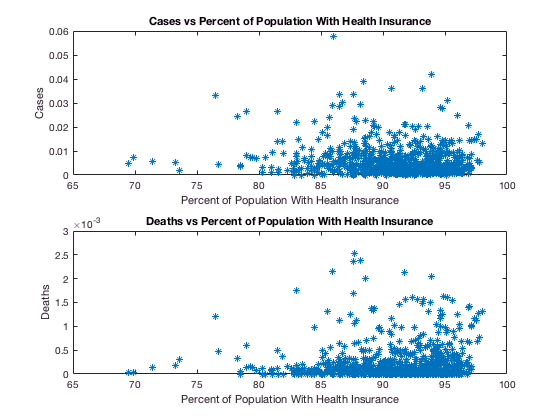


subplot(2,1,2)
plot(Health_Ins_Pct,Deaths, '*')
title("Deaths vs Percent of Population With Health Insurance")
ylabel('Deaths')
xlabel('Percent of Population With Health Insurance')

% Cases vs Poverty pct % 
c = corrcoef(Cases, Poverty_Pct);
c = c(1,2);
fprintf('Correlation coefficent between cases and percent of the population in poverty is %f \n', c)

Correlation coefficent between cases and percent of the population in poverty is 1.101690e-01 



figure(6)
subplot(2,1,1)
plot(Poverty_Pct,Cases,'*')
title("Cases vs Percent of Population in Poverty")
ylabel('Cases')
xlabel('Percent of Population in Poverty')

% Deaths vs Health Insurance pct% 
c = corrcoef(Deaths, Poverty_Pct);
c = c(1,2);
fprintf('Correlation coefficent between deaths and percent of the population in poverty is %f \n', c)

Correlation coefficent between deaths and percent of the population in poverty is 7.867117e-04 


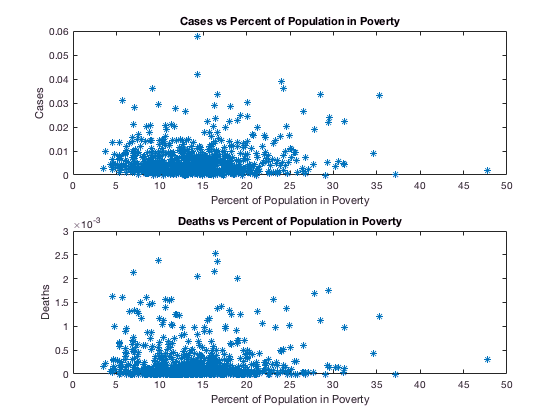


subplot(2,1,2)
plot(Poverty_Pct,Deaths, '*')
title("Deaths vs Percent of Population in Poverty")
ylabel('Deaths')
xlabel('Percent of Population in Poverty')